Setup

addpath(genpath(pwd))
%Please add rFASTCORMICS and Basic Analysis to the path

%optional
set(0,'defaultTextInterpreter','none')
set(groot,'defaulttextinterpreter','none');
set(groot, 'DefaultAxesTickLabelInterpreter', 'none')
set(groot, 'defaultLegendInterpreter','none');

feature astheightlimit 2000

ans = 'feature astHeightLimit 500'


altcolor= [255 255 255;255 204 204; 255 153 153; 255 102 102; 255 51 51;...
    255 0 0; 204 0 0; 152 0 0; 102 0 0;  51 0 0]/255; %shorter 10% = 1 bar

delete clone*.log %delete some files generated by cplex

## 3.1 Expression data input

Import the gene expression data into Matlab. 

data_cancer = readtable('fpkm_BRCA_cancer.txt', "ReadRowNames",true);
data_control = readtable('fpkm_BRCA_control.txt', "ReadRowNames",true);

data = [data_cancer, data_control];

fpkm = table2array(data);
rownames = data.Properties.RowNames;
colnames = data.Properties.VariableNames;

discretization step 

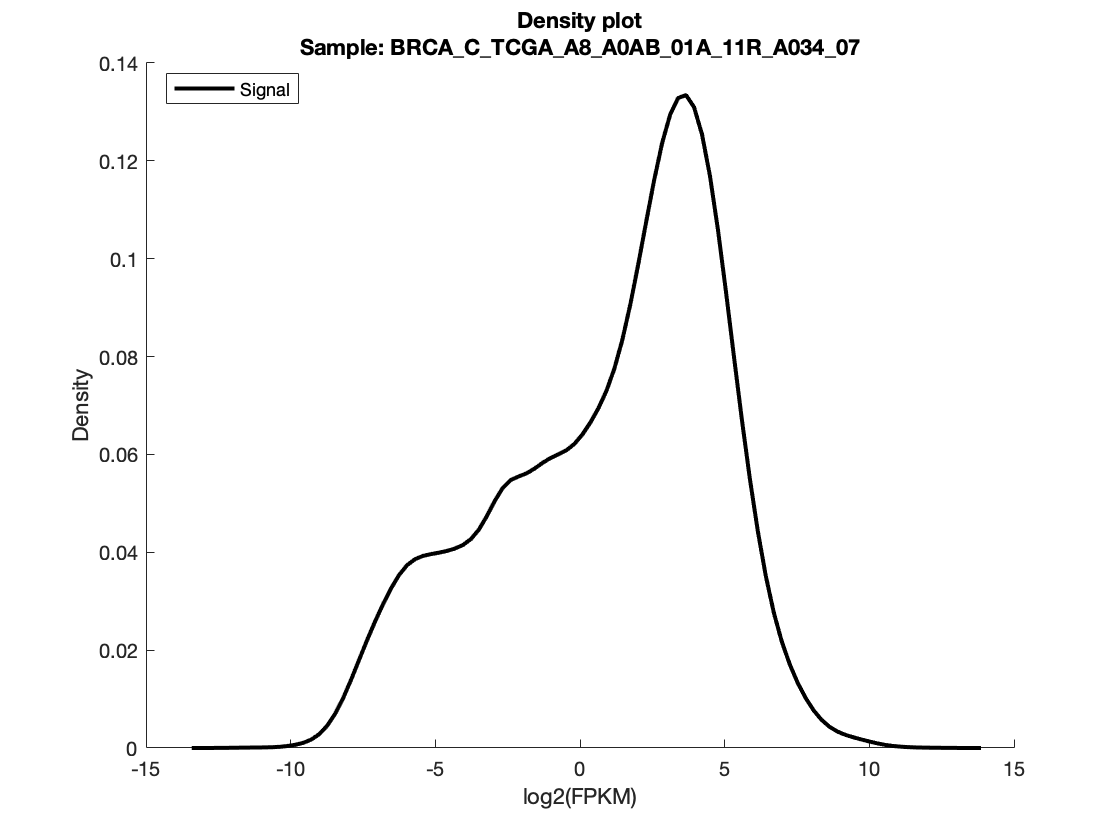

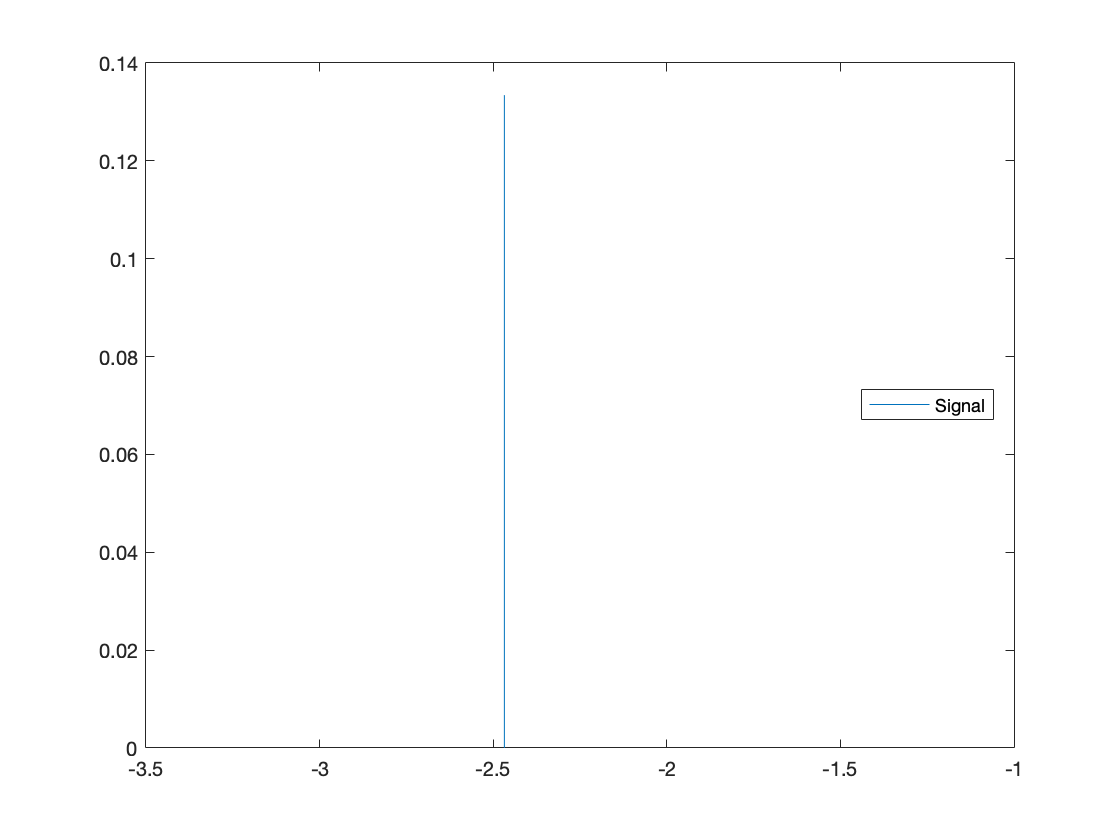

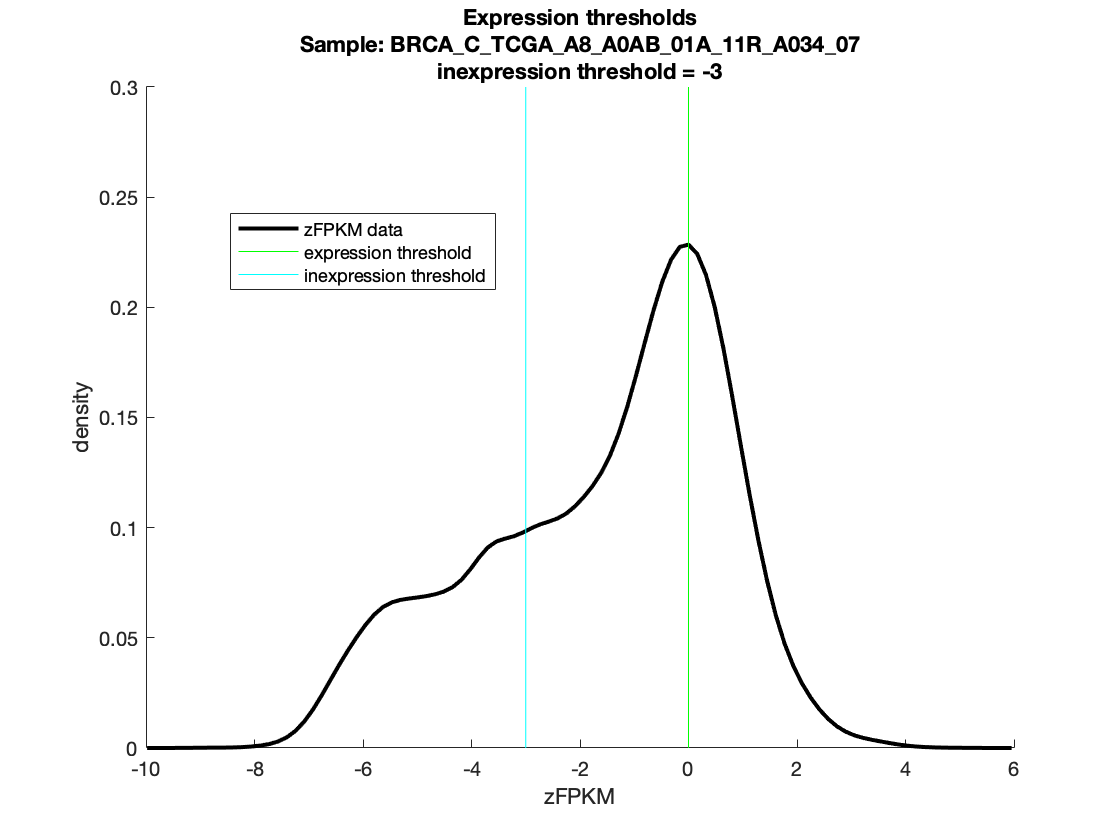

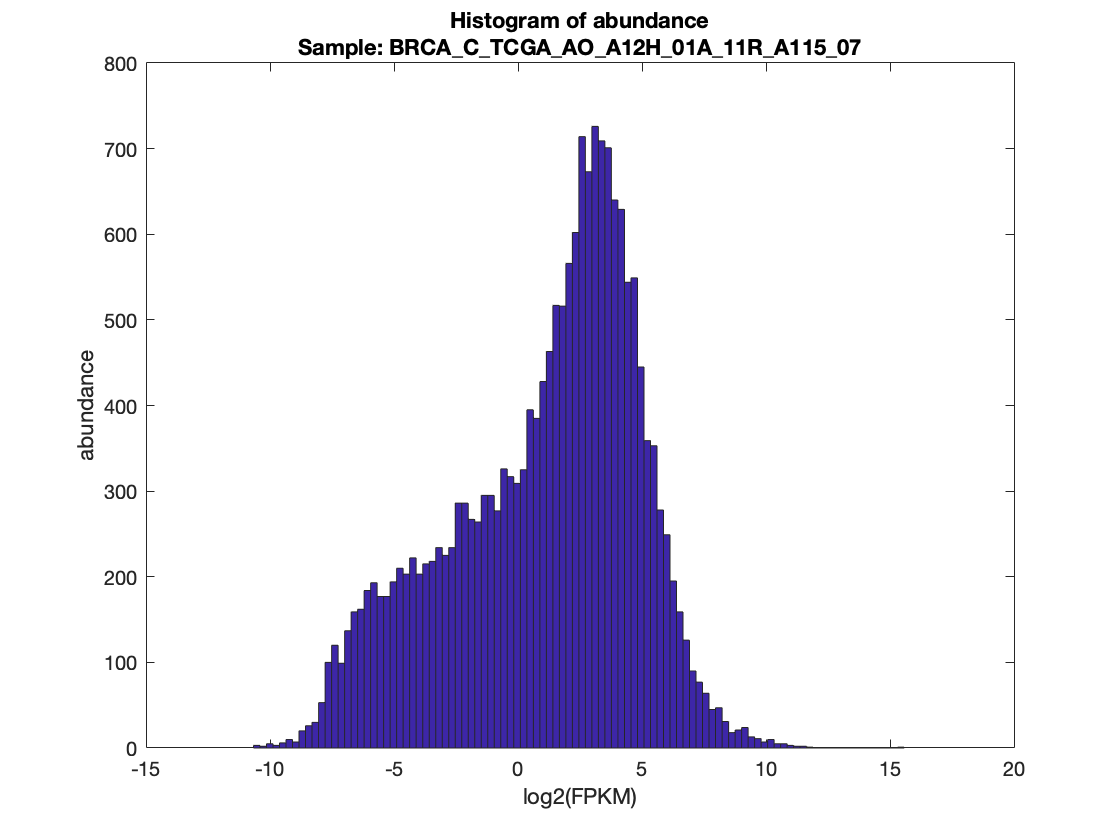

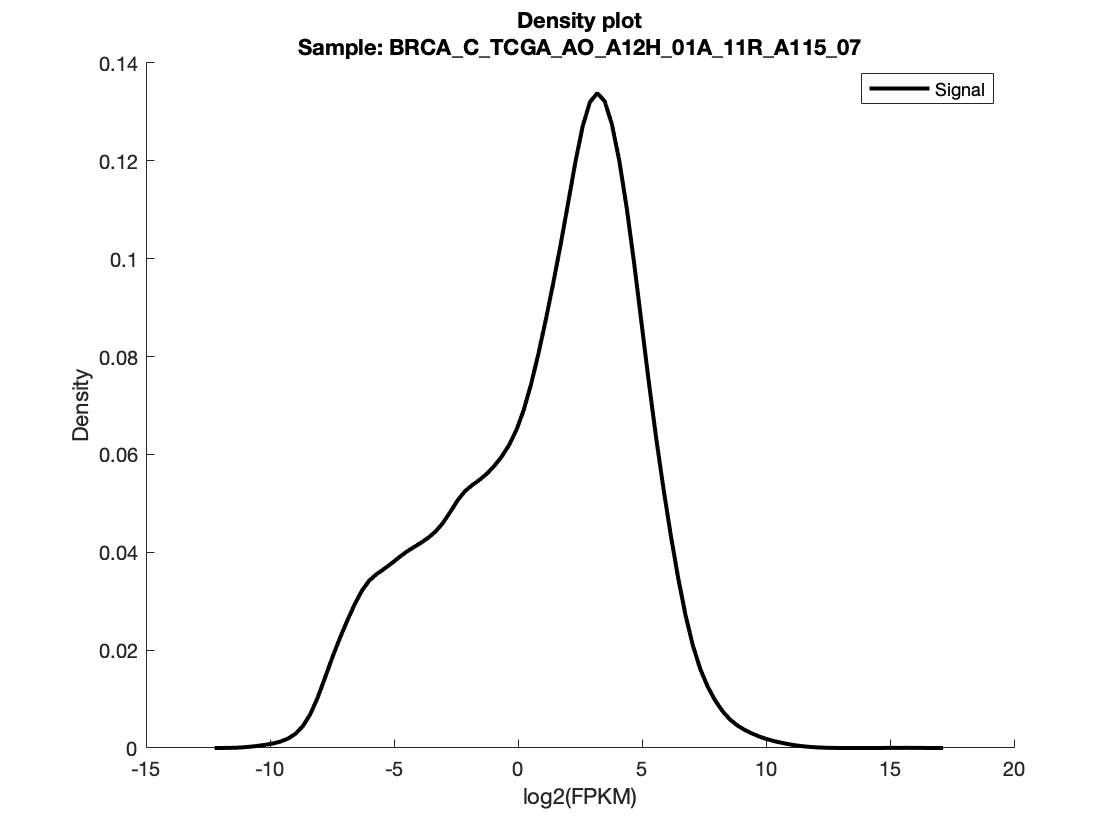

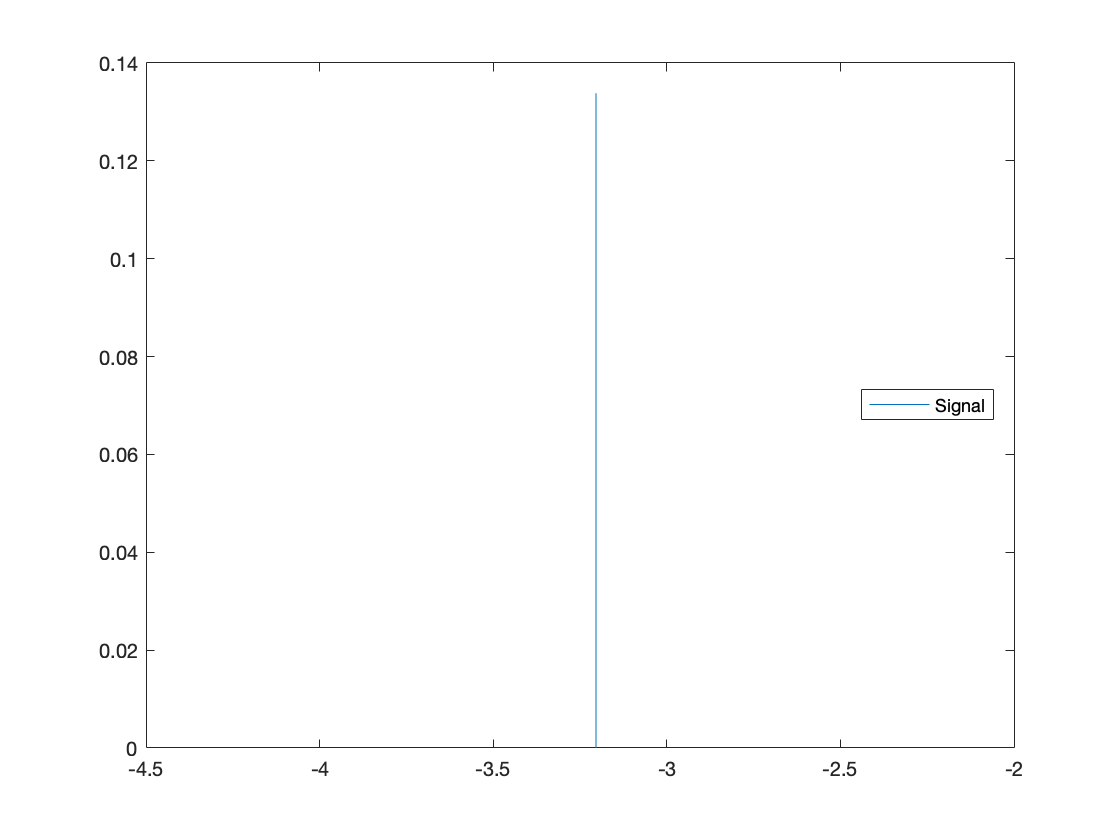

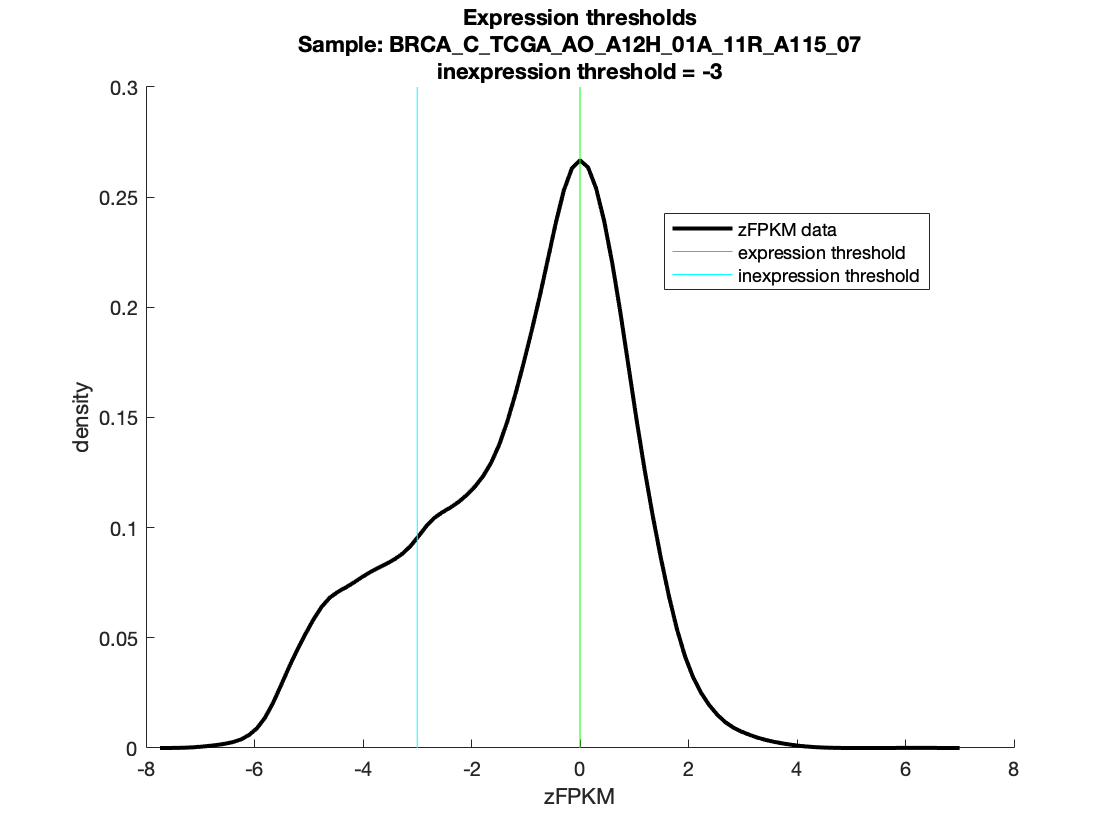

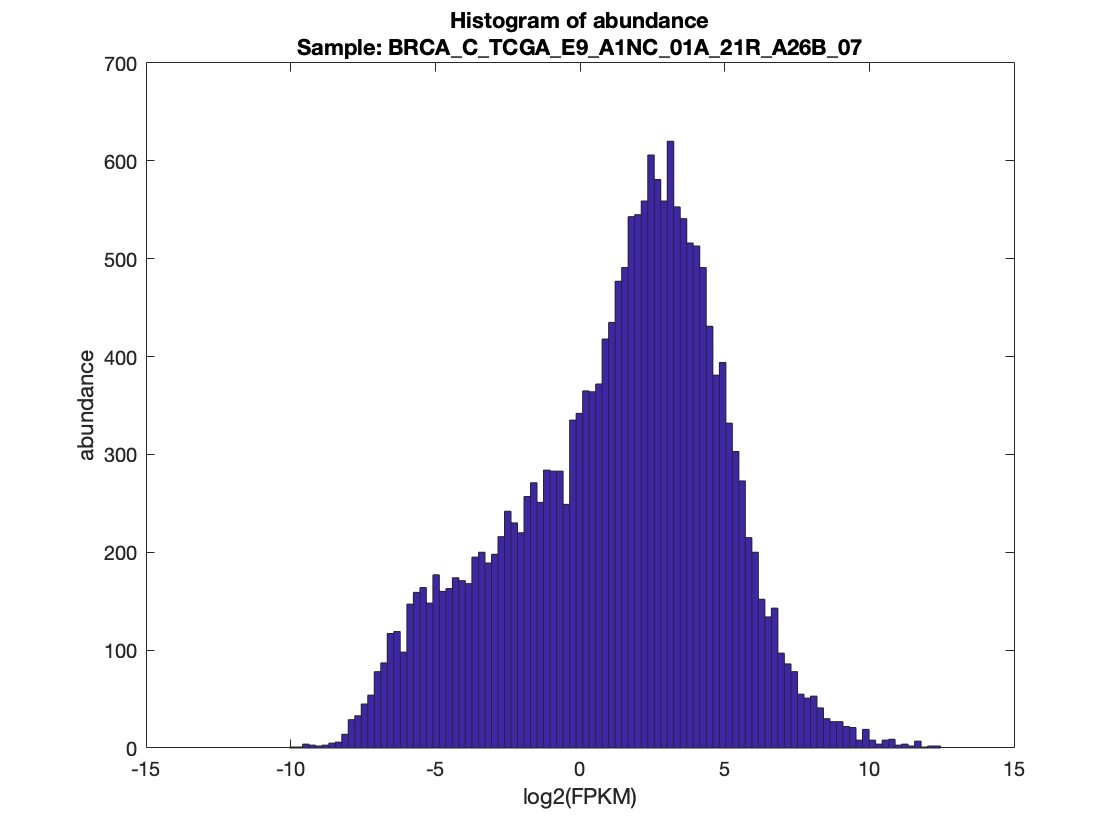

discretized = discretize_FPKM(fpkm, colnames,1); %with figures

%discretized = discretize_FPKM(fpkm, colnames); % no figures

## 3.2.	Context-specific model reconstruction

human reconstruction Recon 2.04 

can also be downloaded from https://www.vmh.life/files/reconstructions/Recon/2.04/Recon2.v04.mat_.zip. 

load Recon2.v04.mat

consitent model creation

A = fastcc_4_rfastcormics(modelR204, 1e-4,0);
consistent_model = removeRxns(modelR204, modelR204.rxns(setdiff(1:numel(modelR204.rxns),A)))

setting parameters

load medium_example.mat
load dico_ML.mat

epsilon = 1e-4
consensus_proportion = 0.9
already_mapped_tag = 0
unpenalizedSystems = {'Transport, endoplasmic reticular';
    'Transport, extracellular';
    'Transport, golgi apparatus';
    'Transport, mitochondrial';
    'Transport, peroxisomal';
    'Transport, lysosomal';
    'Transport, nuclear'};
unpenalized = consistent_model.rxns(ismember(consistent_model.subSystems,unpenalizedSystems));
optional_settings.unpenalized = unpenalized;

optional_settings.func = {'DM_atp_c_', 'biomass_reaction'}; % forced reactions

not_medium_constrained = 'EX_tag_hs(e)';% if no constrain is used please remove the field.
optional_settings.not_medium_constrained = not_medium_constrained;

optional_settings.medium = medium_example;% if no medium is used please remove the field.

biomass_rxn = {'biomass_reaction'};

reconstruct the context-specific models

consensus models

[model_cancer, A_final_cancer] = fastcormics_RNAseq(consistent_model, discretized(:,1:10), rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings)
[model_control, A_final_control] = fastcormics_RNAseq(consistent_model, discretized(:,11:20), rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings)

models_keep_consensus = zeros(numel(consistent_model.rxns), 2);

models_keep_consensus(A_final_cancer,1) = 1
models_keep_consensus(A_final_control,2) = 1

sample-specific models

for i = 1:numel(colnames) %for each sample
    [~, A_keep{i}] = fastcormics_RNAseq(consistent_model, discretized(:,i), ...
        rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings);
end

models_keep = zeros(numel(consistent_model.rxns), numel(colnames));

for i=1:numel(colnames)
    models_keep(A_keep{i},i) = 1;
end

## 3.3.	Basic model and pathway analysis

similarity between two models can be assessed via the Jaccard similarity index

J = squareform(pdist(models_keep','jaccard'));

cgo_J = clustergram(1-J,...
    'RowLabels', colnames,...
    'ColumnLabels', colnames,...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor)

Clustergram object with 20 rows of nodes and 20 columns of nodes.



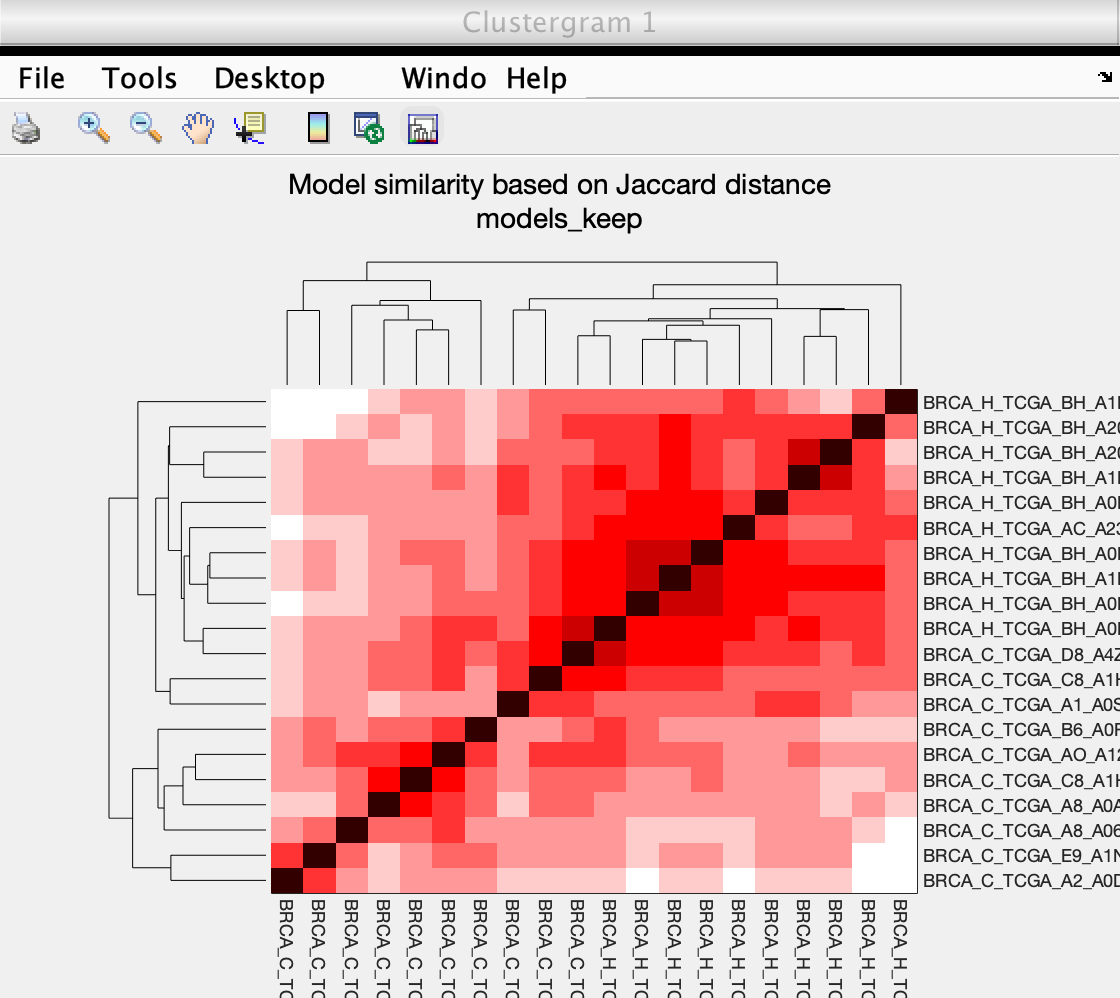

addTitle(cgo_J,{'Model similarity based on Jaccard distance','models_keep'})

Pathway analysis 

Pathways = table(unique(consistent_model.subSystems));
[pathways, ~, ub] = unique(consistent_model.subSystems);
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[I, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.consistent(ia) = T.path_counts(ib);
Pathways.Properties.VariableNames{1}='Pathways';

pathway information for the consensus models

[pathways, ~, ub] = unique(consistent_model.subSystems(find(models_keep_consensus(:,1))));
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[I, ia, ib] = intersect(Pathways.Pathways, T.pathways);
Pathways.Var2(ia) = T.path_counts(ib) ;
Pathways.Properties.VariableNames{3} = 'cancer_consensus';

[pathways, ~, ub] = unique(consistent_model.subSystems(find(models_keep_consensus(:,2))));
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[I, ia, ib] = intersect(Pathways.Pathways, T.pathways);
Pathways.Var2(ia) = T.path_counts(ib);
Pathways.Properties.VariableNames{4} = 'control_consensus';

pathway information for the sample-specific models

for i=1:numel(colnames)
    [pathways, ~, ub] = unique(consistent_model.subSystems(find(models_keep(:,i))));
    path_counts = histc(ub, 1:length(pathways));
    T = table(pathways, path_counts);
    [I, ia, ib] = intersect(Pathways.Pathways, T.pathways);
    Pathways.Var2(ia) = T.path_counts(ib) ;
    Pathways.Properties.VariableNames{4+i} = colnames{i};
end

pathway activity rates

PathwayActivity = Pathways;
for i=3:size(PathwayActivity,2)
    PathwayActivity(:,i) = array2table(table2array(PathwayActivity(:,i))./table2array(PathwayActivity(:,2)));
end
PathwayActivity

PathwayActivity = 90×24 table
                           Var1                           consistent    cancer_consensus    control_consensus    BRCA_C_TCGA_A8_A0AB_01A_11R_A034_07    BRCA_C_TCGA_AO_A12H_01A_11R_A115_07    BRCA_C_TCGA_E9_A1NC_01A_21R_A26B_07    BRCA_C_TCGA_A1_A0SM_01A_11R_A084_07    BRCA_C_TCGA_A2_A0D0_01A_11R_A00Z_07    BRCA_C_TCGA_A8_A06Y_01A_21R_A00Z_07    BRCA_C_TCGA_C8_A1HO_01A_11R_A13Q_07    BRCA_C_TCGA_D8_A4Z1_01A_21R_A266_07    BRCA_C_TCGA_C8_A1HL_01A_11R_A137_07    BRCA_C_TCGA_B6_A0RH_01A_21R_A115_07    BRCA_H_TCGA_BH_A1EO_11A_31R_A137_07    BRCA_H_TCGA_BH_A0DH_11A_31R_A089_07    BRCA_H_TCGA_BH_A204_11A_53R_A157_07    BRCA_H_TCGA_BH_A0BC_11A_22R_A089_07    

### comparison of 2 conditions

pathways with a difference higher than 20% 

diff_idx = find(abs(table2array(PathwayActivity(:,3))- table2array(PathwayActivity(:,4))) > 0.2)

diff_idx =      7
    15
    24
    26
    33
    34
    35
    43
    48
    68


plotting

figure
hold on
scatter(table2array(PathwayActivity(:,3)),table2array(PathwayActivity(:,4)),'filled',...
    'MarkerFaceColor',[0.9 0.9 0.9])
scatter(table2array(PathwayActivity(diff_idx,3)),table2array(PathwayActivity(diff_idx,4)),...
    'black')
ylabel('cancer consensus model')
xlabel('control consensus model')
title('Pathway presence rate in the consensus models')
line([0 1], [0,1],'Color','k')
line([0 0.8], [0.2,1],'Color','k','LineStyle','--')
line([0.2 1], [0,0.8],'Color','k','LineStyle','--')
legend({'All pathways','>20%'},"Location","best")
text(table2array(PathwayActivity(diff_idx,3)),table2array(PathwayActivity(diff_idx,4)), PathwayActivity.Pathways(diff_idx))

comparison of multiple samples

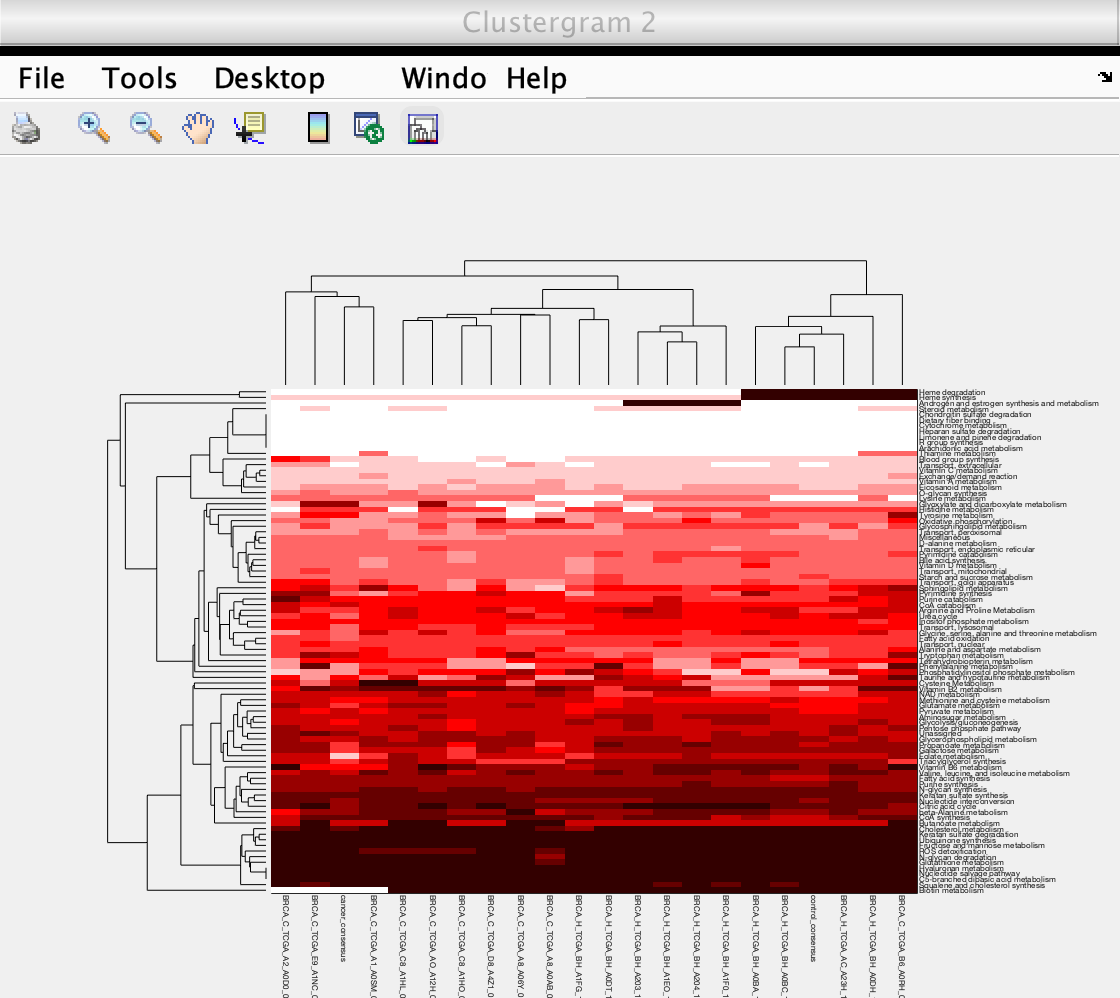

Clustergram object with 90 rows of nodes and 22 columns of nodes.



cgo = clustergram(table2array(PathwayActivity(:,3:end)),...
    'RowLabels', PathwayActivity.Pathways,...
    'ColumnLabels', PathwayActivity.Properties.VariableNames(3:end),...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor)

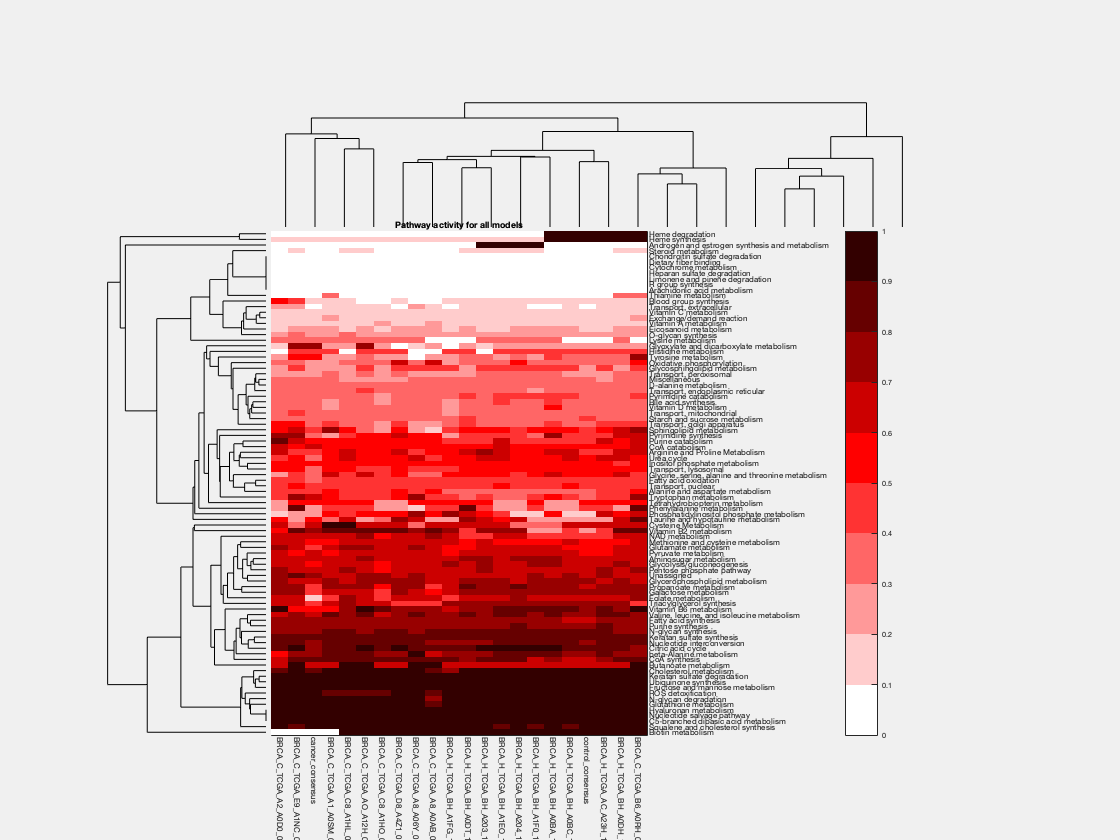

h = plot(cgo); set(h,'TickLabelInterpreter','none');
colorbar(h)
title(h,'Pathway activity for all models')

## 3.4. In silico gene deletion and drug repurposing

set the biomass reaction as objective function:

model_out = changeObjective(consistent_model,'biomass_reaction')

model_out = struct with fields:
                      S: [2960×5317 double]
                   rxns: {5317×1 cell}
                     lb: [5317×1 double]
                     ub: [5317×1 double]
                    rev: [5317×1 double]
                      c: [5317×1 double]
             rxnGeneMat: [5317×2140 double]
                  rules: {5317×1 cell}
                  genes: {2140×1 cell}
                grRules: {5317×1 cell}
             subSystems: {5317×1 cell}
               rxnNames: {5317×1 cell}
              rxnKeggID: {5317×1 cell}
    rxnConfidenceEcoIDA: {5317×1 cell}
    rxnConfidenceScores: {5317×1 cell}
             rxnsboTerm: {5317×1 cell}
          rxnReferences: {5317×1 cell}
           rxnECNumbers: {5317×1 cell}
               rxnNotes: {5317×1 cell}
                   mets: {2960×1 cell}
                      b: [2960×1 double]
               metNames: {2960×1 cell}
            metFormulas: {2960×1 cell}
              metCharge: [2960×1 double]
          

set the ATP demand as objective function

model_out = changeObjective(consistent_model,'DM_atp_c_')

model_out = struct with fields:
                      S: [2960×5317 double]
                   rxns: {5317×1 cell}
                     lb: [5317×1 double]
                     ub: [5317×1 double]
                    rev: [5317×1 double]
                      c: [5317×1 double]
             rxnGeneMat: [5317×2140 double]
                  rules: {5317×1 cell}
                  genes: {2140×1 cell}
                grRules: {5317×1 cell}
             subSystems: {5317×1 cell}
               rxnNames: {5317×1 cell}
              rxnKeggID: {5317×1 cell}
    rxnConfidenceEcoIDA: {5317×1 cell}
    rxnConfidenceScores: {5317×1 cell}
             rxnsboTerm: {5317×1 cell}
          rxnReferences: {5317×1 cell}
           rxnECNumbers: {5317×1 cell}
               rxnNotes: {5317×1 cell}
                   mets: {2960×1 cell}
                      b: [2960×1 double]
               metNames: {2960×1 cell}
            metFormulas: {2960×1 cell}
              metCharge: [2960×1 double]
          

verified with with the checkObjective function 

checkObjective(model_out)

summaryT = 5×5 table
    Coefficient    Metabolite    metID    Reaction     RxnID
    ___________    __________    _____    _________    _____

        -1           h2o[c]       20      DM_atp_c_     791 
        -1           atp[c]       33      DM_atp_c_     791 
         1           adp[c]       35      DM_atp_c_     791 
         1           h[c]         36      DM_atp_c_     791 
         1           pi[c]        37      DM_atp_c_     791 


ans = 1×1 cell array
    {'DM_atp_c_'}


## perform the in silico gene deletion 

initialize the solver

changeCobraSolver('ibm_cplex')

Gurobi installed at this location? 
Licence file current? 
CPXPARAM_Output_WriteLevel                       3
CPXPARAM_Output_CloneLog                         -1
Found incumbent of value 0.000000 after 838.24 sec. (0.00 ticks)

Root node processing (before b&c):
  Real time             =  838.25 sec. (0.00 ticks)
Parallel b&c, 8 threads:
  Real time             =    0.00 sec. (0.00 ticks)
  Sync time (average)   =    0.00 sec.
  Wait time (average)   =    0.00 sec.
                          ------------
Total (root+branch&cut) =  838.25 sec. (0.00 ticks)
Could not find installation of tomlab_cplex, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of quadMinos, so it cannot be tested
Could not find installation of dqqMinos, so it cannot be tested
Could not find installation of cplex_direct, so it cannot be tested

 > [cplexlp] Primal optimality condition in solveCobraLP satisfied.
 > [cplexlp] Dual optimality condition in so

ans = logical
   1


 run the single gene deletion

for i=1:size(models_keep,2) %for each model

grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 828.1951

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


    
    %ATP
    ind = find(~cellfun(@isempty, regexp(consistent_model.rxns, 'DM_atp_c_')));
    model_out = removeRxns(consistent_model,consistent_model.rxns(setdiff(1:numel(consistent_model.rxns),find(models_keep(:,i))))); % create model based on active reactions
    model_out = changeObjective(model_out,consistent_model.rxns(ind));
    
    [grRatio, grRateKO, grRateWT, hasEffect, delRxns, fluxSolution] = singleGeneDeletion_rFASTCORMICS(model_out,'FBA',[],0,1);
    
    grRatio_ATP(:,i)    = grRatio;
    grRateKO_ATP(:,i)   = grRateKO;
    grRateWT_ATP(:,i)   = grRateWT;
    
    %Biomass
    ind = find(~cellfun(@isempty, regexp(consistent_model.rxns, 'biomass_reaction')));
    model_out = removeRxns(consistent_model,consistent_model.rxns(setdiff(1:numel(consistent_model.rxns),find(models_keep(:,i))))); % create model based on active reactions
    model_out = changeObjective(model_out,consistent_model.rxns(ind));
    
    [grRatio, grRateKO, grRateWT, hasEffect, delRxns, fluxSolution, genelist] = singleGeneDeletion_rFASTCORMICS(model_out,'FBA',[],0,1);
    
    grRatio_biomass(:,i)    = grRatio;
    grRateKO_biomass(:,i)   = grRateKO;
    grRateWT_biomass(:,i)   = grRateWT;
    
end

## determination of cancer-specific essential genes

[B, ia, ib] = intersect(genelist,dico.ENTREZ)

B = 1729×1 cell array
    {'100'      }
    {'10005'    }
    {'10007'    }
    {'100137049'}
    {'10020'    }
    {'10026'    }
    {'100287639'}
    {'10050'    }
    {'100526794'}
    {'10057'    }
    {'10060'    }
    {'10087'    }
    {'10090'    }
    {'10135'    }
    {'10157'    }
    {'10164'    }
    {'10165'    }
    {'10166'    }
    {'10195'    }
    {'10201'    }
    {'10229'    }
    {'10246'    }
    {'10249'    }
    {'10257'    }
    {'102724560'}
    {'10312'    }
    {'10317'    }
    {'10327'    }
    {'10331'    }
    {'1036'     }


ia =      1
     2
     3
     4
     5
     6
     7
     8
    10
    11


ib =           79
          55
         716
        1217
         713
        1171
         965
        1388
        1058
          18


genelist(ia, 2) =   dico.SYMBOL(ib)

genelist = 1733×2 cell array
    {'100'      }    {'ADA'         }
    {'10005'    }    {'ACOT8'       }
    {'10007'    }    {'GNPDA1'      }
    {'100137049'}    {'PLA2G4B'     }
    {'10020'    }    {'GNE'         }
    {'10026'    }    {'PIGK'        }
    {'100287639'}    {'MTHFD2P1'    }
    {'10050'    }    {'SLC17A4'     }
    {'100507855'}    {0×0 double    }
    {'100526794'}    {'NT5C1B-RDH14'}
    {'10057'    }    {'ABCC5'       }
    {'10060'    }    {'ABCC9'       }
    {'10087'    }    {'COL4A3BP'    }
    {'10090'    }    {'UST'         }
    {'10135'    }    {'NAMPT'       }
    {'10157'    }    {'AASS'        }




essential_cancer_genes = genelist(sum(grRatio_biomass(:,1:10) < 0.5,2) > 5,2)

essential_cancer_genes = 15×1 cell array
    {'SPTLC1'}
    {'PTPMT1'}
    {'DHCR7' }
    {'DTYMK' }
    {'KDSR'  }
    {'SGMS1' }
    {'GUK1'  }
    {'CMPK1' }
    {'PKM'   }
    {'CRLS1' }
    {'SPTLC3'}
    {'TXNRD1'}
    {'SLC7A5'}
    {'PGS1'  }
    {'SPTLC2'}


essential_control_genes = genelist(sum(grRatio_ATP(:,11:20) < 0.9,2) > 1,2)

essential_control_genes = 23×1 cell array
    {'SLC25A10'}
    {'DBI'     }
    {'FH'      }
    {'RPIA'    }
    {'SLC25A6' }
    {'SLC29A2' }
    {'PNP'     }
    {'PC'      }
    {'DERA'    }
    {'PKLR'    }
    {'PKM'     }
    {'PGM2'    }
    {'PRODH'   }
    {'RPE'     }
    {'SDHA'    }
    {'SDHB'    }
    {'SDHC'    }
    {'SDHD'    }
    {'SLC16A1' }
    {'SLC22A5' }
    {'TXNRD1'  }
    {'SLC25A16'}
    {'SLC25A11'}




cancer_specific_genes = setdiff(essential_cancer_genes, essential_control_genes)

cancer_specific_genes = 13×1 cell array
    {'CMPK1' }
    {'CRLS1' }
    {'DHCR7' }
    {'DTYMK' }
    {'GUK1'  }
    {'KDSR'  }
    {'PGS1'  }
    {'PTPMT1'}
    {'SGMS1' }
    {'SLC7A5'}
    {'SPTLC1'}
    {'SPTLC2'}
    {'SPTLC3'}


## Drug deletion

define a list of drugs 

load GeneDrugRelations.mat
DrugList = unique(GeneDrugRelations.DrugName)

DrugList = 1175×1 cell array
    {'(1,10 Phenanthroline)-(Tri-Carbon Monoxide) Rhenium (I)'}
    {'(R)-Rolipram'                                           }
    {'(S)-Rolipram'                                           }
    {'2-mercaptobenzothiazole'                                }
    {'4-Methoxyamphetamine'                                   }
    {'5-methyltetrahydrofolic acid'                           }
    {'6-Deoxyerythronolide B'                                 }
    {'7-ethyl-10-hydroxycamptothecin'                         }
    {'AB192'                                                  }
    {'AVE9633'                                                }
    {'Abemaciclib'                                            }
    {'Abiraterone'                                            }
    {'Acalabrutinib'                                          }
    {'Acarbose'                                               }
    {'Acebutolol'                                             }
    {'Acecl



for i=1:size(models_keep,2)
    
    %ATP
    ind = find(~cellfun(@isempty, regexp(consistent_model.rxns, 'DM_atp_c_')));
    model_out = removeRxns(consistent_model,consistent_model.rxns(setdiff(1:numel(consistent_model.rxns),find(models_keep(:,i)))));
    model_out = changeObjective(model_out,consistent_model.rxns(ind));
    
    [grRatio, grRateKO, grRateWT] = DrugDeletion(model_out,'FBA',DrugList);
    
    Drug_grRatio_ATP(:,i)    = grRatio;
    Drug_grRateKO_ATP(:,i)   = grRateKO;
    Drug_grRateWT_ATP(:,i)   = grRateWT;
    
    %Biomass
    ind = find(~cellfun(@isempty, regexp(consistent_model.rxns, 'biomass_reaction')));
    model_out = removeRxns(consistent_model,consistent_model.rxns(setdiff(1:numel(consistent_model.rxns),find(models_keep(:,i)))));
    model_out = changeObjective(model_out,consistent_model.rxns(ind));
    
    [grRatio, grRateKO, grRateWT] =  DrugDeletion(model_out,'FBA',DrugList);
    
    Drug_grRatio_biomass(:,i)    = grRatio;
    Drug_grRateKO_biomass(:,i)   = grRateKO;
    Drug_grRateWT_biomass(:,i)   = grRateWT;
    
end

grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1000

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 828.1951

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 1.6889

Single gene deletion analysis in progress ...
100%    [........................................]


## cancer-specific drugs for repurposing

cancer_drugs = DrugList(sum(Drug_grRatio_biomass(:,1:10) < 0.5,2) > 5)

cancer_drugs = 2×1 cell array
    {'Cladribine' }
    {'Gemcitabine'}


control_drugs = DrugList(sum(Drug_grRatio_ATP(:,11:20) < 0.9,2) > 1)

control_drugs = 59×1 cell array
    {'Acetoacetic Acid'  }
    {'Acetylcholine'     }
    {'Aldosterone'       }
    {'Aminohippuric acid'}
    {'Ampicillin'        }
    {'Azidocillin'       }
    {'Benzylpenicillin'  }
    {'Cefadroxil'        }
    {'Cefalotin'         }
    {'Cefdinir'          }
    {'Cefepime'          }
    {'Cefixime'          }
    {'Cefradine'         }
    {'Ceftazidime'       }
    {'Cephalexin'        }
    {'Cephaloglycin'     }
    {'Choline'           }
    {'Choline salicylate'}
    {'Cimetidine'        }
    {'Cladribine'        }
    {'Clodronic acid'    }
    {'Clonidine'         }
    {'Creatine'          }
    {'Cyclacillin'       }
    {'D-Lactic acid'     }
    {'Dactinomycin'      }
    {'Desipramine'       }
    {'Diphenhydramine'   }
    {'Dopamine'          }
    {'Furosemide'        }




cancer_specific_drugs = setdiff(cancer_drugs, control_drugs)

cancer_specific_drugs = 1×1 cell array
    {'Gemcitabine'}
